# ELEX7620 Lab 2

Name:  Ryan Wong, A00958475, and set:T

Objective:  to simulate and measure a 2nd order Butterworth lowpass filter

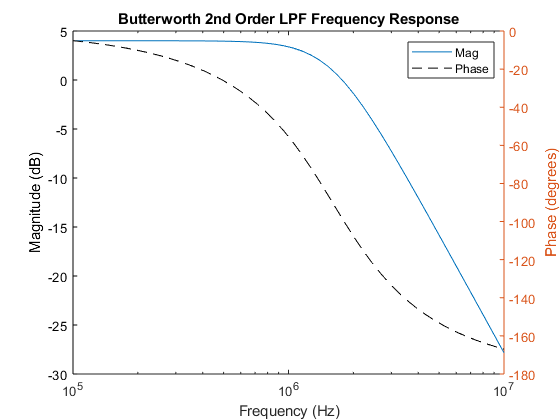

fc=1.6e6;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
zeta = sqrt(2)^(-1);
k = -sqrt(2) + 3;

%modify the code below to create the transfer function
%store transfer function in variable name H
b = k * wc^2;
a = [1 2*zeta*wc wc^2];
H = tf(b,a);

%plot the frequency response
freq = logspace(5,7,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Butterworth 2nd Order LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Calculate Component Values for Sallen Key Active Filter

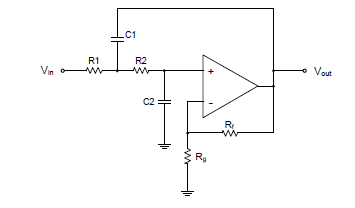

%Show your work for the steps below by inserting some documentation above or below this code block


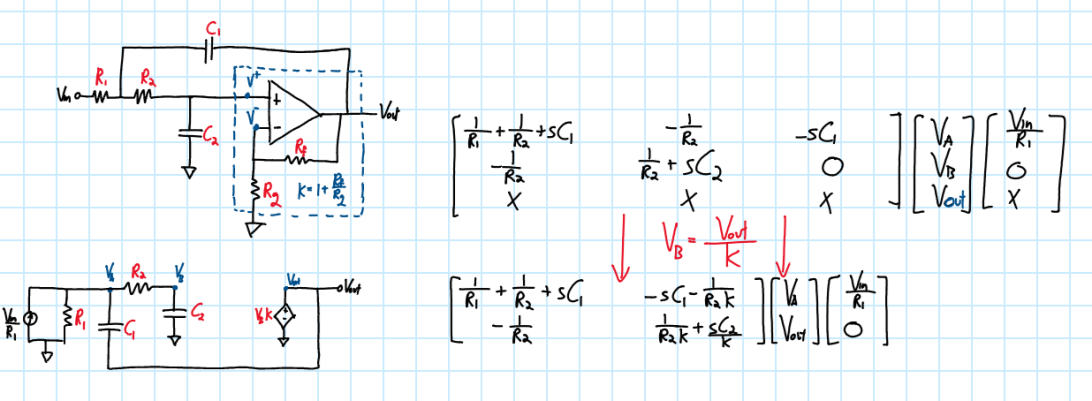

%using matlab to solve the matrix

%r1 =/= r2
%c1 =/= c2
% syms s r1 r2 c1 c2 k
% A = [(1/r1)+(1/r2)+s*c1 -s*c1-(r2*k)^(-1)
%      -1/r2 (r2*k)^(-1)+((s*c2)/k)];
% B = [r1^(-1); 0];


%Where r1 = r2 & c1 = c2
syms s r c k
A = [(1/r)+(1/r)+s*c -s*c-(r*k)^(-1);
    -1/r (r*k)^(-1)+((s*c)/k)];
B = [r^(-1); 0];
X = linsolve(A,B);
Simplified = collect(X(2,1), s)

$$Simplified = \frac{k}{\left(c^{2}\,r^{2}\right)\,s^{2}+\left(3\,c\,r-c\,k\,r\right)\,s+1}$$

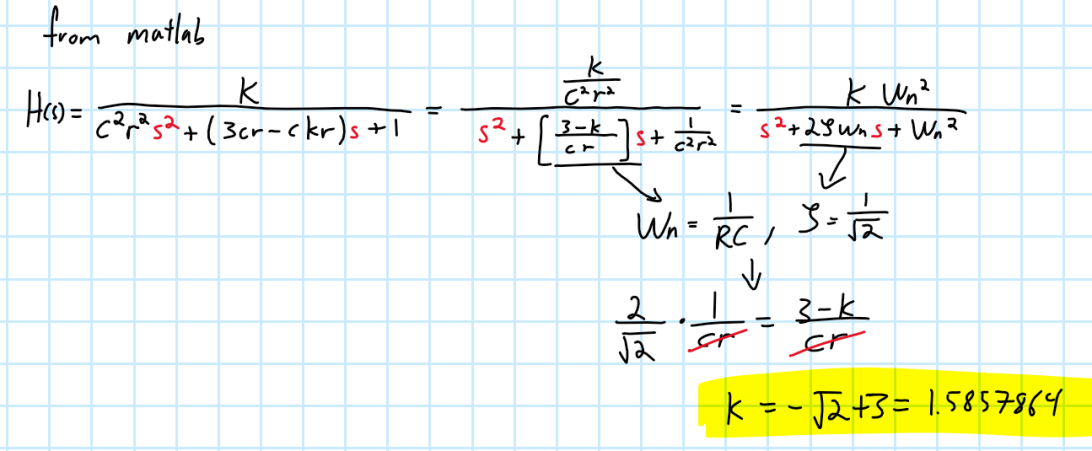

% 100pF for c1 & c2
r = (100e-12 * wc)^(-1)

r = 994.7184

%1k ohms for r1 & r2

%set rg = 1k ohm
rf = (1.585786438 - 1) * 1000

rf = 585.7864

## LTSPICE Schematic

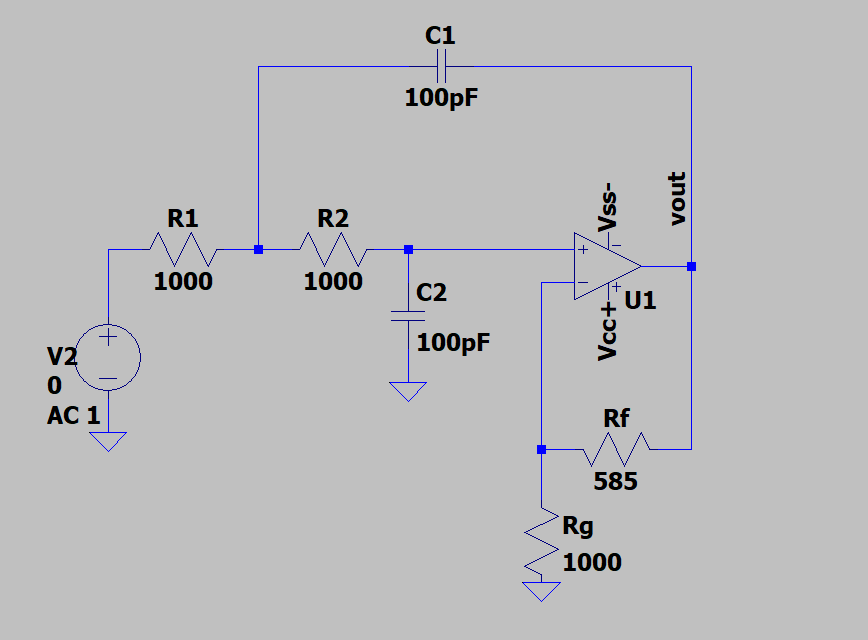

## LTSPICE Simulation Results

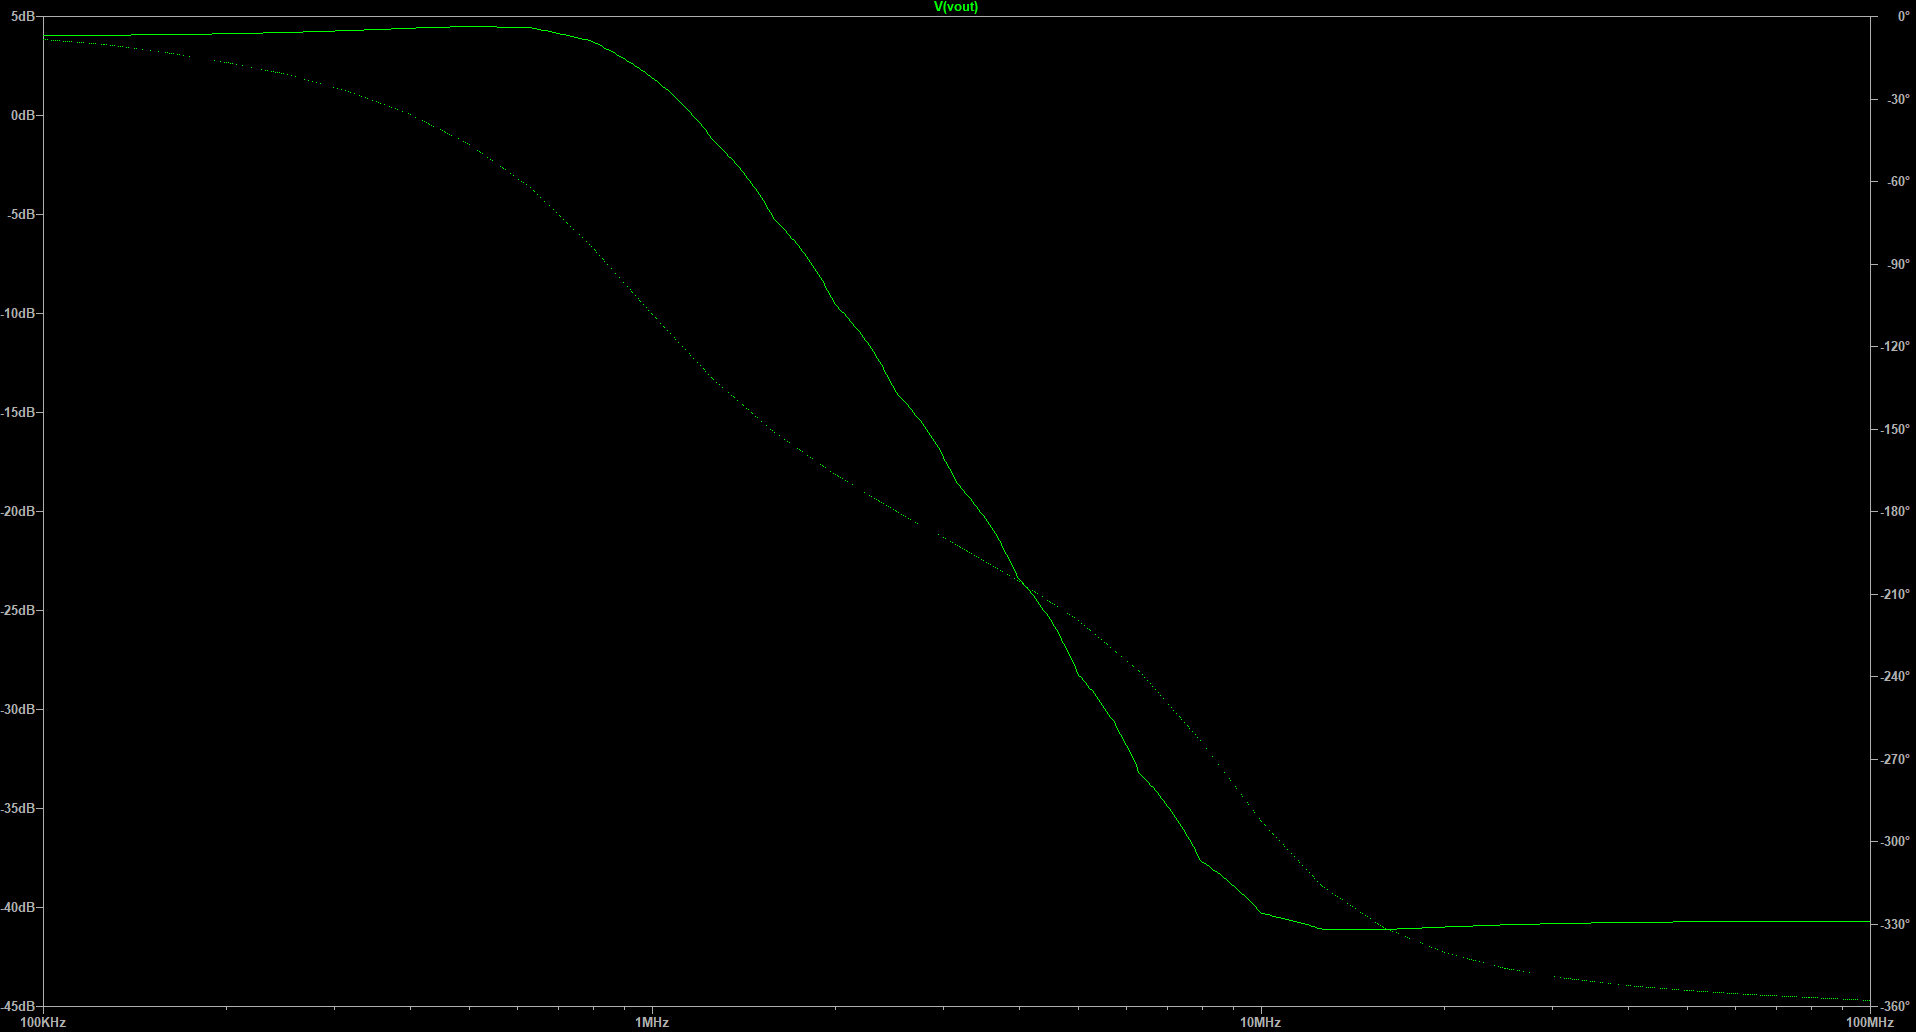

## Measurements

Record your measured data here and compare it against the theoretical results

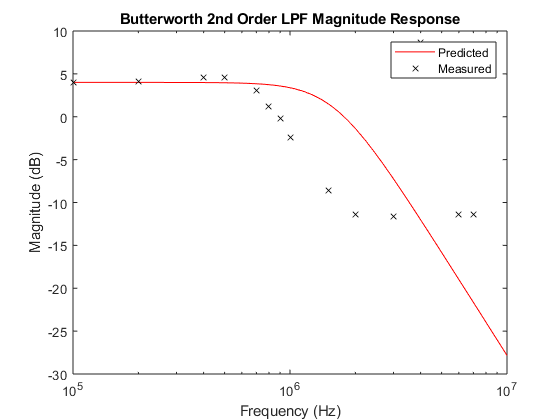

%Measured data; each triplet [f,vout,delay] is
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[500e3, 0.188, 392e-9 ]
    [400e3, 0.188, 328e-9]
    [100e3, 0.176, 260e-9]
    [200e3, 0.178, 340e-9]
    [700e3, 0.158, 441e-9]
    [800e3, 0.128, 500e-9]
    [900e3, 0.108, 520e-9]
    [1e6, 0.084, 476e-9]
    [1.5e6, 0.041, 358e-9]
    [2e6, 0.030, 306e-9]
    [3e6, 0.029, 286e-9]
    [4e6, 0.30, 230e-9]
    [6e6, 0.03, 154e-9]
    [7e6, 0.03, 134e-9]
    ];

%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 0.111;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);
meas_delay = measured(:,3);
meas_phase = (-1)*360*meas_delay.*meas_freq;

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Butterworth 2nd Order LPF Magnitude Response')
legend('Predicted', 'Measured')

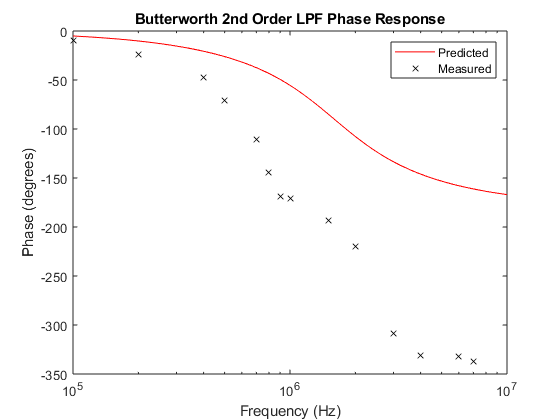


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Butterworth 2nd Order LPF Phase Response')
legend('Predicted', 'Measured')

## Post-Lab Analysis

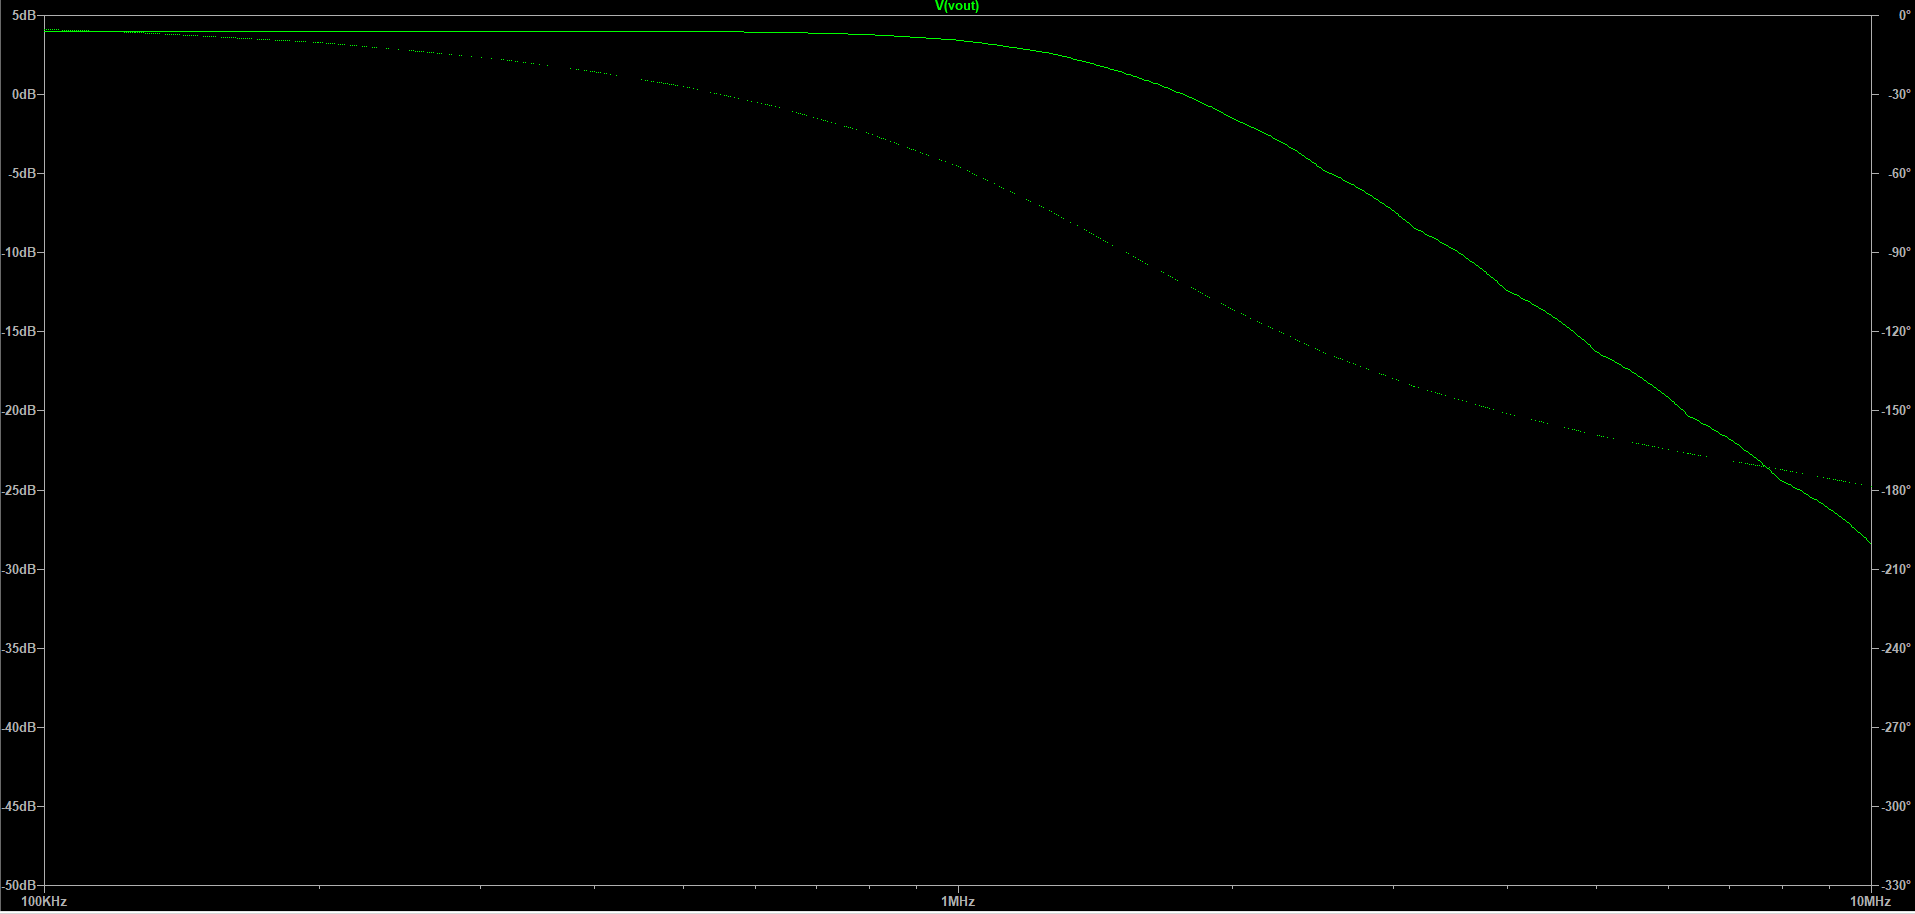

Increasing the GBWP to 100MHz, I can achieve the desired 1.6MHz cut-off frequency 